# TB2kp

## matlab中的泰勒展开

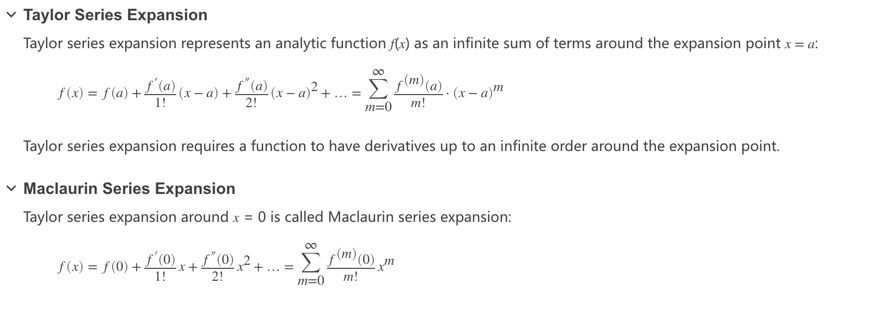

### 一元展开

syms x
T1 = taylor(exp(x))

$$T1 = 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}+\frac{x^{4}}{24}+\frac{x^{5}}{120}$$

T2 = taylor(sin(x))

$$T2 = x-\frac{x^{3}}{6}+\frac{x^{5}}{120}$$

T3 = taylor(cos(x))

$$T3 = 1-\frac{x^{2}}{2}+\frac{x^{4}}{24}$$

You can use the sympref function to modify the output order of symbolic polynomials. Redisplay the polynomials in ascending order.

#### 给出顺序

% 
% sympref('PolynomialDisplayStyle','ascend');
% T1
% T2
% T3
% sympref('default');

#### 确定展开点

Find the Taylor series expansions at *x* = 1 for these functions. 

The default expansion point is 0.

syms x
T = taylor(log(x), x, 'ExpansionPoint', 1)

$$T = x-\frac{{\left(-1+x\right)}^{2}}{2}+\frac{{\left(-1+x\right)}^{3}}{3}-\frac{{\left(-1+x\right)}^{4}}{4}+\frac{{\left(-1+x\right)}^{5}}{5}-1$$

#### 确定展开阶

syms x
f = sin(x)/x;
T6 = taylor(f, x)

$$T6 = 1-\frac{x^{2}}{6}+\frac{x^{4}}{120}$$

Use `Order` to control the truncation order. For example, approximate the same expression up to the orders 8 and 10:

T8 = taylor(f, x, 'Order', 8)

$$T8 = 1-\frac{x^{2}}{6}+\frac{x^{4}}{120}-\frac{x^{6}}{5040}$$

T10 = taylor(f, x, 'Order', 10) 

$$T10 = 1-\frac{x^{2}}{6}+\frac{x^{4}}{120}-\frac{x^{6}}{5040}+\frac{x^{8}}{362880}$$

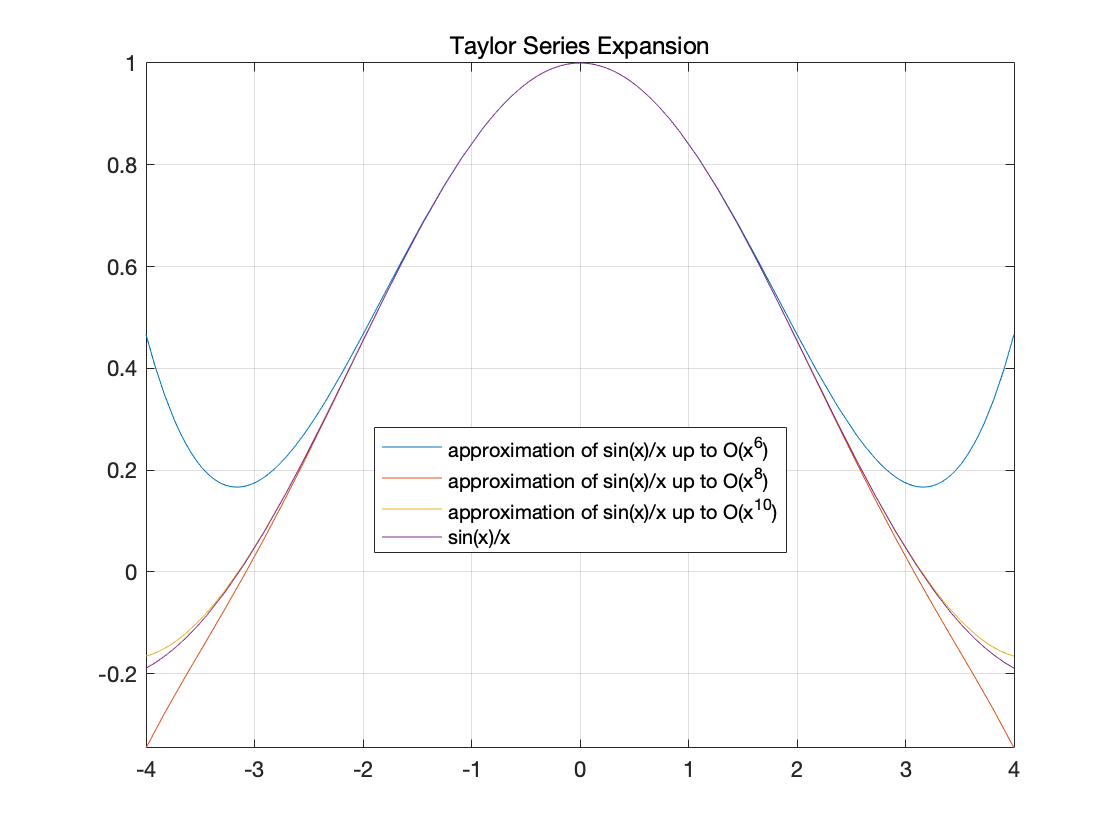

fplot([T6 T8 T10 f])
xlim([-4 4])
grid on

legend('approximation of sin(x)/x up to O(x^6)',...
       'approximation of sin(x)/x up to O(x^8)',...
       'approximation of sin(x)/x up to O(x^{10})',...
       'sin(x)/x','Location','Best')
title('Taylor Series Expansion')

### 多元展开

Find the multivariate Taylor expansion by specifying both the vector of variables and the vector of values defining the expansion point:

syms x y
f = y*exp(x - 1) - x*log(y);
T = taylor(f, [x, y], [1, 1], 'Order', 3)

$$T = x+\frac{{\left(-1+x\right)}^{2}}{2}+\frac{{\left(-1+y\right)}^{2}}{2}$$

If you specify the expansion point as a scalar `a`, `taylor` transforms that scalar into a vector of the same length as the vector of variables. All elements of the expansion vector equal `a`:

T = taylor(f, [x, y], 1, 'Order', 3)

$$T = x+\frac{{\left(-1+x\right)}^{2}}{2}+\frac{{\left(-1+y\right)}^{2}}{2}$$

## 石墨烯

### 课本解法

**Followed with the book *****Modern Condensed Matter Physics *****written by Steven M. Girvin and Kun Yang. **

、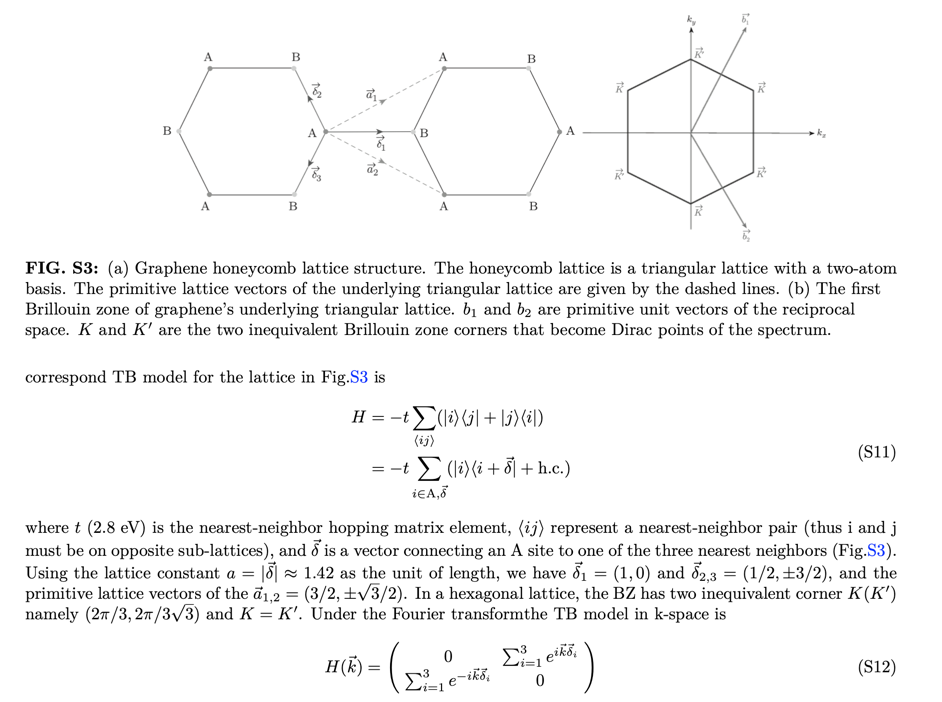		

	 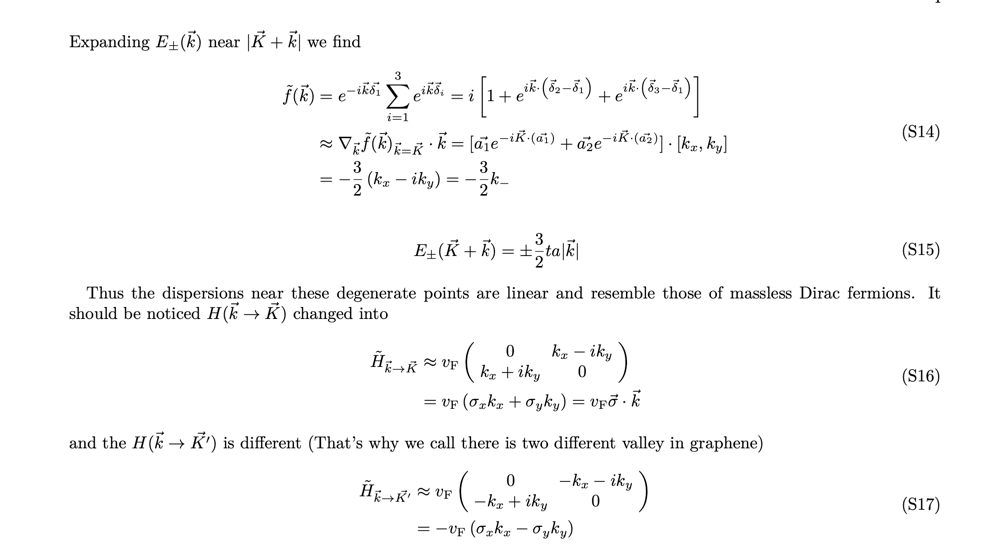

### 创建模型

- 声明一个空的模型；初始化其轨道数

Graphene = HR(2)

Graphene =   HR - 属性:

     vectorL: [0 0 0]
       HnumL: [2×2 double]
       HcoeL: [2×2 sym]
       NRPTS: 1
     WAN_NUM: 2
    Line_000: 1


- 修改POSCAR格式

*generated by phonopy*

*   1.0*

*     2.4604399204208875    0.0000000000000000    0.0000000000000000*

*    -1.2302199602104438    2.1308034755698513    0.0000000000000000*

*     0.0000000000000000    0.0000000000000000   10.0000000000000000*

*C*

*   2*

*Direct*

*  0.6666666666666666  0.3333333333333333  0.0000000000000000 *`C p z `

*  0.3333333333333334  0.6666666666666667  0.0000000000000000 *`C p z`

- 导入POSCAR

Graphene = Graphene <'POSCAR'

Graphene =   HR - 属性:

     vectorL: [0 0 0]
       HnumL: [2×2 double]
       HcoeL: [2×2 sym]
       NRPTS: 1
     WAN_NUM: 2
    Line_000: 1


- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 0];
Accuracy = 3;
r_max_search = 2;
Graphene = Graphene.nn_sk_smart(search_range,Accuracy ,r_max_search);

The (   1/   2) th orb nn information has been generated.
The (   2/   2) th orb nn information has been generated.
Giving (   1/   2) th orb nn_level ... 
Giving (   2/   2) th orb nn_level ... 


- 这里我们取最近邻hopping

level_cut = 1;
per_dir = [1 1 0];
Graphene = Graphene.H_TB_gen_SK(level_cut,per_dir);

setting (   1/   2) th orbital ... 
setting (   2/   2) th orbital ... 


- 查看一下体系的未知量（symbolic）

Graphene.symvar_list

$$ans = {\mathrm{VppP}}_{1}$$

Graphene.Rm;
Graphene.orbL;
syms a;
%Graphene.Rm = sym(a*[3/2  sqrt(3)/2  0; 3/2 -sqrt(3)/2 0; 0 0 10]);
Graphene.Rm = sym(a*[sqrt(3) 0  0; -sqrt(3)/2 3/2 0; 0 0 10]);
%Graphene.orbL = sym([0 0 0;1/3 1/3 0]);
Graphene.orbL = sym([2/3 1/3 0;1/3 2/3 0]);
rank = 2;

K_f = sym([1/3 1/3 0]);
K_prime_f = -K_f;
Gk = (2*pi*eye(3)/Graphene.Rm).';
K = K_f*Gk;
K_prime_ = K_f*Gk;

zero_mat = zeros(Graphene.WAN_NUM);
syms k_x k_y k_z real;
% k_z = 0;
k_vector = [k_x k_y k_z].';
H_tmp = HK(2);
test_Delta = 0;
for n = 1:Graphene.NRPTS
    vector = Graphene.vectorL(n,:);
    for i = 1:Graphene.WAN_NUM
        orb1 = Graphene.orbL(i,:);
        for j = 1:Graphene.WAN_NUM
            orb2 = Graphene.orbL(j,:);
            tmp_mat = zero_mat;
            tmp_mat(i,j) = 1;
            if Graphene.HcoeL(i,j,n) ~= sym(0)
                %disp(Graphene.HcoeL(i,j,n) );
%                 disp( (vector+orb2-orb1));
                %                     tmp_sym= rm_constant(exp(1i * ( (vector+orb2-orb1) * Graphene.Rm )* k_vector ));
                %                     tmp_sym=exp(1i * ( (vector+orb2-orb1) * Graphene.Rm )* k_vector );
                tmp_sym=exp(1i * ( (vector+orb2-orb1) * Graphene.Rm )* (k_vector+[K(1), K(2),K(3)].' ));
                test_Delta = test_Delta +tmp_sym;
                T = simplify(taylor(tmp_sym, [k_x, k_y,k_z ], 'Order', 2));
                if T~=sym(0)
%                     disp(tmp_sym);
                    H_tmp = H_tmp + ...
                        Term(Graphene.HcoeL(i,j,n)*T ,tmp_mat);
                end
            end
            
        end
        
    end
end

setting 3th (y) Hk
setting 2th (x) Hk
setting 1th (1) Hk
setting 3th (y) Hk
setting 2th (x) Hk
setting 1th (1) Hk
setting 2th (x) Hk
setting 3th (y) Hk
setting 1th (1) Hk
setting 3th (y) Hk
setting 1th (1) Hk
setting 3th (y) Hk
setting 1th (1) Hk
setting 2th (x) Hk
setting 3th (y) Hk
setting 1th (1) Hk


Hk_sym = simplify(H_tmp.Hk_sym);
latex(Hk_sym);
syms t real;
VppP_1 = -t;
Hk_sym  = subs(Hk_sym);
    eig(Hk_sym);


$$\left(\begin{array}{cc} 0 & \frac{3\,\mathrm{VppP}_{1}\,a\,\left(1+\sqrt{3}\,1{}\mathrm{i}\right)\,\left(-k_{y}\,1{}\mathrm{i}+k_{x}\right)}{4}\\ -\frac{\mathrm{VppP}_{1}\,a\,\left(k_{y}\,1{}\mathrm{i}+k_{x}\right)\,\left(\sqrt{3}+1{}\mathrm{i}\right)\,3{}\mathrm{i}}{4} & 0 \end{array}\right)$$


    function output_sym = rm_constant(input_sym)
    [A,B] = coeffs(input_sym);
    %         tmp_sym = 0;
    if B(end) ~= sym(1)
        output_sym = input_sym;
    else
        output_sym = input_sym- B(end)*A(end);
    end
    
    end